% % Définir le chemin d'accès racine qui contient les images
% rootFolderPath = 'data/scalo';
% 
% % Définir le filtre de fichiers pour n'inclure que les images
% fileFilter = '*.jpg';
% 
% % Trouver tous les fichiers correspondant au filtre dans tous les sous-dossiers
% imageFiles = dir(fullfile(rootFolderPath, '**', fileFilter));
% 
% % Pour chaque fichier d'image trouvé
% for i = 1:length(imageFiles)
%     % Construire le chemin d'accès complet pour le fichier
% 
%     imagePath = fullfile(imageFiles(i).folder, imageFiles(i).name);
%     
%     % Lire l'image
%     image = imread(imagePath);
%     
%     % Redimensionner l'image à 224x224
%     image_resized = imresize(image, [224, 224]);
%     
%     % Sauvegarder l'image redimensionnée au même emplacement
%     imwrite(image_resized, imagePath);
% end


allImages = imageDatastore(fullfile('data/data_train/'),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');
rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);

Number of training images: 146


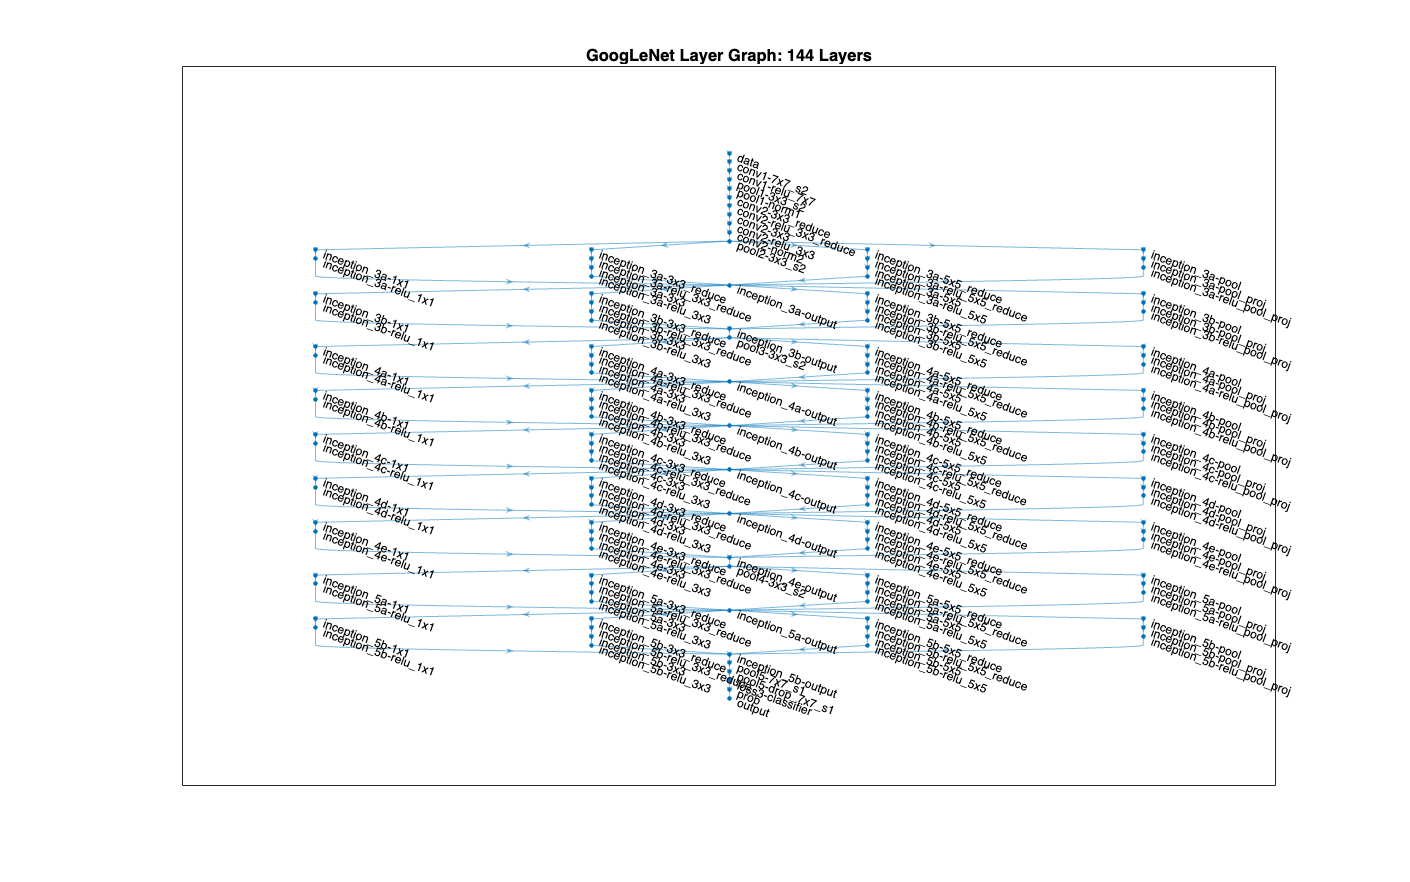

net = googlenet;
lgraph = layerGraph(net);
numberOfLayers = numel(lgraph.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)
title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);

net.Layers(1);

newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraph = replaceLayer(lgraph,['pool5-dro' ...
    'p_7x7_s1'],newDropoutLayer);
numClasses = numel(categories(imgsTrain.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);

options = trainingOptions('sgdm',...
    'MiniBatchSize', 30,...
    'MaxEpochs', 20,...
    'InitialLearnRate', 1e-4,...
    'ValidationData', imgsValidation,...
    'ValidationFrequency', 10,...
    'Verbose', 1,...
    'ExecutionEnvironment', 'cpu',... 
    'Plots', 'training-progress'); 

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:17 |       33.33% |       50.00% |       2.6291 |       1.1897 |      1.0000e-04 |
|       3 |          10 |       00:01:26 |       46.67% |       50.00% |       1.2687 |       0.8707 |      1.0000e-04 |
|       5 |          20 |       00:02:37 |       66.67% |       50.00% |       0.7844 |       0.7078 |      1.0000e-04 |
|       8 |          30 |       00:03:49 |       40.00% |       55.56% |       0.7681 |       0.6817 |      1.0000

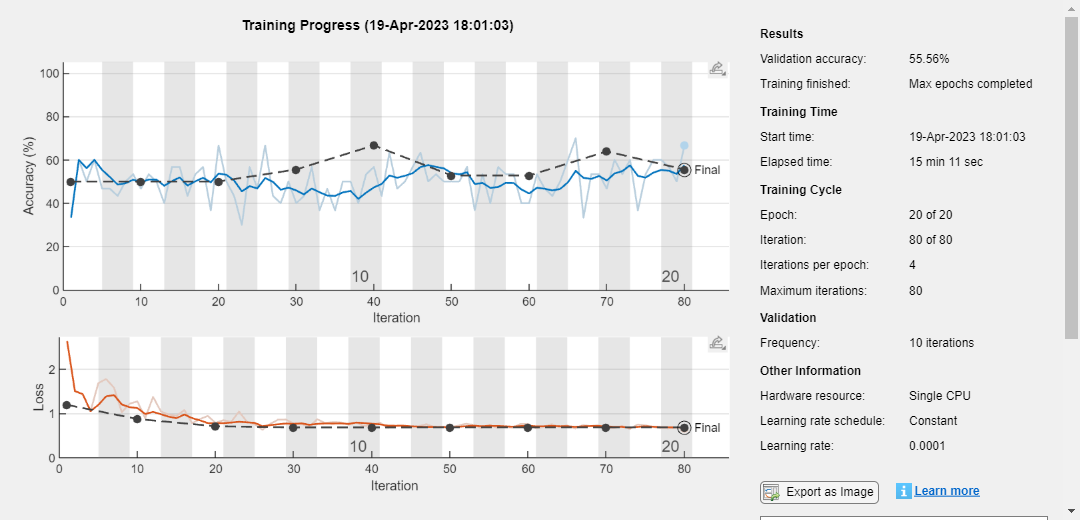

trainedGN = trainNetwork(imgsTrain,lgraph,options);

% Test the performance of the trained model on the validation set
load("model.mat")
predictedLabels = classify(trainedGN, imgsValidation);
accuracy = mean(predictedLabels == imgsValidation.Labels);
fprintf('Accuracy on validation set: %0.2f%%\n', accuracy * 100);

Accuracy on validation set: 55.56%


save('model.mat', 'trainedGN')